# Calculate daily generation of NYAM units

## Import the RGGI generation data

clear;
% Import hourly generation data of generators in RGGI database in the 2019 whole year
generationDataStore = fileDatastore(".\2019\emission*.csv", "ReadFcn", @importGenerationData, "UniformRead", true);
generationAll = readall(generationDataStore);

## Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Remove unused categories
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);

## Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
generationAllJoint = innerjoin(generationAll,generatorCombiner,'Keys',...
    {'FacilityName','FacilityID','UnitID'}, 'LeftVariables', {'FacilityName',...
    'FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'OperatingTime'})

generationAllJoint = 1454160×13 table
    FacilityName    FacilityID    UnitID       Date       Hour    GrossLoadMW    OperatingTime    NYISOname    PTID     NYAMUnit    Region         UnitType          FuelType  
    ____________    __________    ______    __________    ____    ___________    _____________    _________    _____    ________    ______    __________________    ___________

    23rd and 3rd       7910        2301     01/01/2019      0          0               0          Gowanus 5    24156      J-CT        J       Combustion turbine    Nat

## Calculate daily power generation of each NYAM units

### Subset generation total time series dataset by NYAM units

genA2FCC = generationAllJoint(generationAllJoint.NYAMUnit == "A2F-CC", :);
genA2FST = generationAllJoint(generationAllJoint.NYAMUnit == "A2F-ST", :);
genGHIST = generationAllJoint(generationAllJoint.NYAMUnit == "GHI-ST", :);
genJCC = generationAllJoint(generationAllJoint.NYAMUnit == "J-CC", :);
genJCT = generationAllJoint(generationAllJoint.NYAMUnit == "J-CT", :);
genJST = generationAllJoint(generationAllJoint.NYAMUnit == "J-ST", :);
genKCT = generationAllJoint(generationAllJoint.NYAMUnit == "K-CT", :);
genKST = generationAllJoint(generationAllJoint.NYAMUnit == "K-ST", :);

### Calculate daily power generation

genDailyA2FCC = groupsummary(genA2FCC, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyA2FST = groupsummary(genA2FST, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyGHIST = groupsummary(genGHIST, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyJCC = groupsummary(genJCC, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyJCT = groupsummary(genJCT, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyJST = groupsummary(genJST, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyKCT = groupsummary(genKCT, ["Date", "Hour"], "sum", "GrossLoadMW");
genDailyKST = groupsummary(genKST, ["Date", "Hour"], "sum", "GrossLoadMW");

## Write daily generation of NYAM units into a file

genDailyAll = table(genDailyA2FCC.Date, genDailyA2FCC.Hour, genDailyA2FCC.sum_GrossLoadMW, ...
    genDailyA2FST.sum_GrossLoadMW, genDailyGHIST.sum_GrossLoadMW, genDailyJCC.sum_GrossLoadMW, ...
    genDailyJCT.sum_GrossLoadMW, genDailyJST.sum_GrossLoadMW, genDailyKCT.sum_GrossLoadMW, ...
    genDailyKST.sum_GrossLoadMW, 'VariableNames', ["Date", "Hour", "A2FCC", "A2FST", ...
    "GHIST", "JCC", "JCT", "JST", "KCT", "KST"])

genDailyAll = 8760×10 table
       Date       Hour    A2FCC    A2FST    GHIST    JCC     JCT    JST    KCT    KST
    __________    ____    _____    _____    _____    ____    ___    ___    ___    ___

    01/01/2019      0      208       0        0      1270     0     101    82     237
    01/01/2019      1      116       0        0      1156     0      99    38     246
    01/01/2019      2      115       0        0      1109     0      99    31     246
    01/01/2019      3      117       0        0      1073     0      98    31     245
    01/01/2019      4      116       0        0      1020     0      98    31     246
    01/01/2019      5      14

writetable(genDailyAll, '.\genDailyAll2019.csv', "Delimiter", ',');

## Finding the lowest power generation

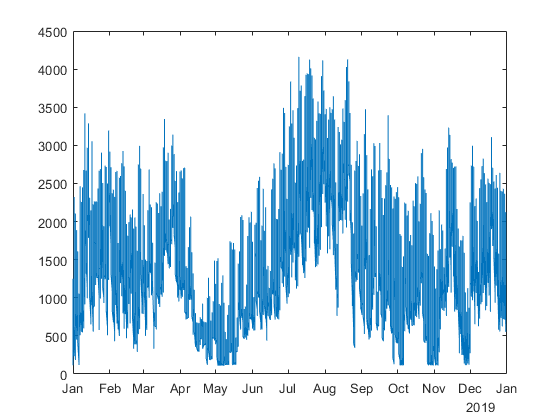

figure(5);
reset(gcf)

plot(genDailyAll.Date, genDailyAll.A2FCC)

## Generation for specific dates for NYAM modeling

% date1 = 'Jan-19-2016';
% date2 = 'Mar-22-2016';
% date3 = 'Jul-25-2016';
% date4 = 'Nov-10-2016';
genAllDate1 = genDailyAll(genDailyAll.Date == '01/15/2019', :);
genAllDate2 = genDailyAll(genDailyAll.Date == '03/22/2019', :);
genAllDate3 = genDailyAll(genDailyAll.Date == '07/25/2019', :);
genAllDate4 = genDailyAll(genDailyAll.Date == '11/10/2019', :);

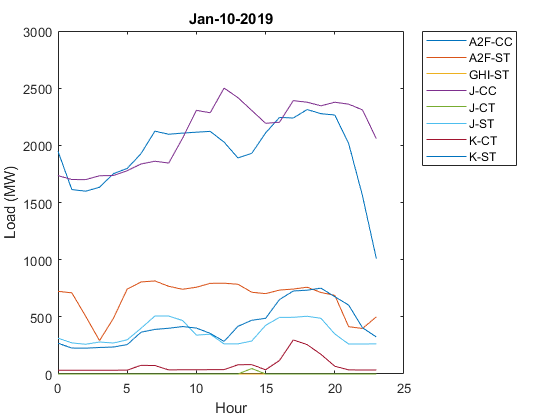

figure(1)
plot(genAllDate1.Hour, [genAllDate1.A2FCC, genAllDate1.A2FST, genAllDate1.GHIST, ...
    genAllDate1.JCC, genAllDate1.JCT, genAllDate1.JST, genAllDate1.KCT, genAllDate1.KST]);
legend('A2F-CC', 'A2F-ST', 'GHI-ST', 'J-CC', 'J-CT', 'J-ST', 'K-CT', 'K-ST', 'Location', 'bestoutside');
xlabel('Hour');
ylabel('Load (MW)');
title("Jan-10-2019");

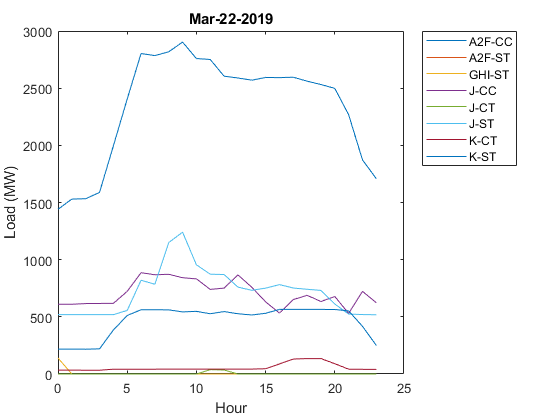

figure(2)
plot(genAllDate2.Hour, [genAllDate2.A2FCC, genAllDate2.A2FST, genAllDate2.GHIST, ...
    genAllDate2.JCC, genAllDate2.JCT, genAllDate2.JST, genAllDate2.KCT, genAllDate2.KST]);
legend('A2F-CC', 'A2F-ST', 'GHI-ST', 'J-CC', 'J-CT', 'J-ST', 'K-CT', 'K-ST', 'Location', 'bestoutside');
xlabel('Hour');
ylabel('Load (MW)');
title("Mar-22-2019");

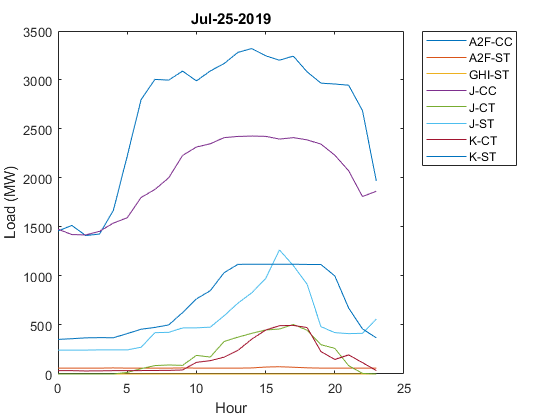

figure(3)
plot(genAllDate3.Hour, [genAllDate3.A2FCC, genAllDate3.A2FST, genAllDate3.GHIST, ...
    genAllDate3.JCC, genAllDate3.JCT, genAllDate3.JST, genAllDate3.KCT, genAllDate3.KST]);
legend('A2F-CC', 'A2F-ST', 'GHI-ST', 'J-CC', 'J-CT', 'J-ST', 'K-CT', 'K-ST', 'Location', 'bestoutside');
xlabel('Hour');
ylabel('Load (MW)');
title("Jul-25-2019");

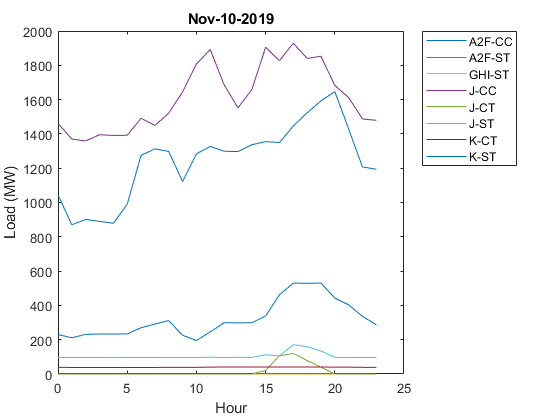

figure(4)
plot(genAllDate4.Hour, [genAllDate4.A2FCC, genAllDate4.A2FST, genAllDate4.GHIST, ...
    genAllDate4.JCC, genAllDate4.JCT, genAllDate4.JST, genAllDate4.KCT, genAllDate4.KST]);
legend('A2F-CC', 'A2F-ST', 'GHI-ST', 'J-CC', 'J-CT', 'J-ST', 'K-CT', 'K-ST', 'Location', 'bestoutside');
xlabel('Hour');
ylabel('Load (MW)');
title("Nov-10-2019");

## Daily variation of total generation in NYCA

### Subset by seasons

generationAllJointSpring = generationAllJoint(generationAllJoint.Date >= '03/01/2019' & generationAllJoint.Date < '06/01/2019' | ismissing(generationAllJoint.Date),:);
generationAllJointSummer = generationAllJoint(generationAllJoint.Date >= '06/01/2019' & generationAllJoint.Date < '09/01/2019',:);
generationAllJointAutumn = generationAllJoint(generationAllJoint.Date >= '09/01/2019' & generationAllJoint.Date < '12/01/2019',:);
generationAllJointWinter = generationAllJoint((generationAllJoint.Date >= '01/01/2019' & generationAllJoint.Date < '03/01/2019') | ...
    (generationAllJoint.Date >= '12/01/2019' & generationAllJoint.Date <= '12/31/2019'),:);

generationSpringDaily = groupsummary(generationAllJointSpring, "Hour", "sum", "GrossLoadMW");
generationSummerDaily = groupsummary(generationAllJointSummer, "Hour", "sum", "GrossLoadMW");
generationAutumnDaily = groupsummary(generationAllJointAutumn, "Hour", "sum", "GrossLoadMW");
generationWinterDaily = groupsummary(generationAllJointWinter, "Hour", "sum", "GrossLoadMW");

### Plot daily variation of total generation in each season

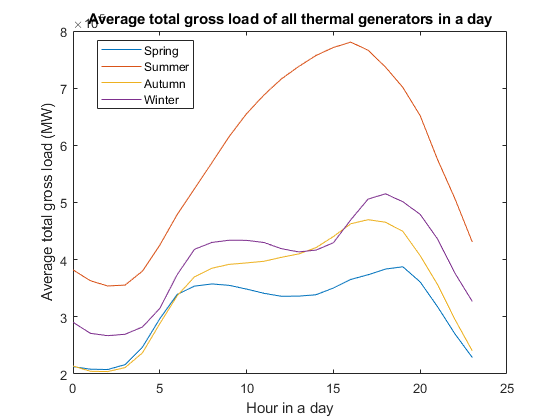

fPlot1 = figure(9);
hold on;
p_spring = plot(generationSpringDaily.Hour, generationSpringDaily.sum_GrossLoadMW);
p_summer = plot(generationSummerDaily.Hour, generationSummerDaily.sum_GrossLoadMW);
p_autumn = plot(generationAutumnDaily.Hour, generationAutumnDaily.sum_GrossLoadMW);
p_winter = plot(generationWinterDaily.Hour, generationWinterDaily.sum_GrossLoadMW);
legend([p_spring, p_summer, p_autumn, p_winter], ["Spring", "Summer", "Autumn", "Winter"], 'Location', "best");
xlabel("Hour in a day");
ylabel("Average total gross load (MW)");
title("Average total gross load of all thermal generators in a day");
box on;
hold off;

## Daily average power generation of each NYAM units in each season

### Subset by NYAM Units and seasons

A2F_CC_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "A2F-CC", :), "Hour", "sum", "GrossLoadMW");
A2F_CC_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "A2F-CC", :), "Hour", "sum", "GrossLoadMW");
A2F_CC_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "A2F-CC", :), "Hour", "sum", "GrossLoadMW");
A2F_CC_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "A2F-CC", :), "Hour", "sum", "GrossLoadMW");
A2F_ST_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "A2F-ST", :), "Hour", "sum", "GrossLoadMW");
A2F_ST_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "A2F-ST", :), "Hour", "sum", "GrossLoadMW");
A2F_ST_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "A2F-ST", :), "Hour", "sum", "GrossLoadMW");
A2F_ST_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "A2F-ST", :), "Hour", "sum", "GrossLoadMW");
GHI_ST_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "GHI-ST", :), "Hour", "sum", "GrossLoadMW");
GHI_ST_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "GHI-ST", :), "Hour", "sum", "GrossLoadMW");
GHI_ST_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "GHI-ST", :), "Hour", "sum", "GrossLoadMW");
GHI_ST_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "GHI-ST", :), "Hour", "sum", "GrossLoadMW");
J_CC_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "J-CC", :), "Hour", "sum", "GrossLoadMW");
J_CC_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "J-CC", :), "Hour", "sum", "GrossLoadMW");
J_CC_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "J-CC", :), "Hour", "sum", "GrossLoadMW");
J_CC_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "J-CC", :), "Hour", "sum", "GrossLoadMW");
J_CT_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "J-CT", :), "Hour", "sum", "GrossLoadMW");
J_CT_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "J-CT", :), "Hour", "sum", "GrossLoadMW");
J_CT_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "J-CT", :), "Hour", "sum", "GrossLoadMW");
J_CT_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "J-CT", :), "Hour", "sum", "GrossLoadMW");
J_ST_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "J-ST", :), "Hour", "sum", "GrossLoadMW");
J_ST_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "J-ST", :), "Hour", "sum", "GrossLoadMW");
J_ST_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "J-ST", :), "Hour", "sum", "GrossLoadMW");
J_ST_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "J-ST", :), "Hour", "sum", "GrossLoadMW");
K_CT_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "K-CT", :), "Hour", "sum", "GrossLoadMW");
K_CT_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "K-CT", :), "Hour", "sum", "GrossLoadMW");
K_CT_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "K-CT", :), "Hour", "sum", "GrossLoadMW");
K_CT_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "K-CT", :), "Hour", "sum", "GrossLoadMW");
K_ST_SpringDaily = groupsummary(generationAllJointSpring(generationAllJointSpring.NYAMUnit == "K-ST", :), "Hour", "sum", "GrossLoadMW");
K_ST_SummerDaily = groupsummary(generationAllJointSummer(generationAllJointSummer.NYAMUnit == "K-ST", :), "Hour", "sum", "GrossLoadMW");
K_ST_AutumnDaily = groupsummary(generationAllJointAutumn(generationAllJointAutumn.NYAMUnit == "K-ST", :), "Hour", "sum", "GrossLoadMW");
K_ST_WinterDaily = groupsummary(generationAllJointWinter(generationAllJointWinter.NYAMUnit == "K-ST", :), "Hour", "sum", "GrossLoadMW");

### Plot daily average by season of each NYAM units

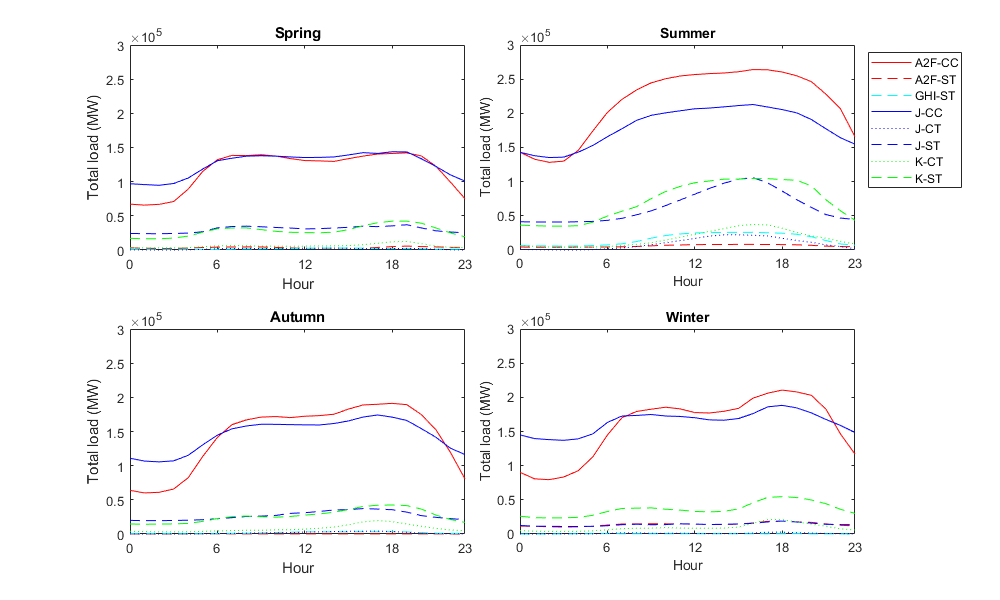

fPlot2 = figure(10);
reset(fPlot2);
set(fPlot2, 'units', 'pixels', 'Position', [100, 100, 800, 600], 'visible', 'off');
% Spring
ax1 = subplot(2,2,1);
plot(A2F_CC_SpringDaily.Hour, A2F_CC_SpringDaily.sum_GrossLoadMW, 'r-');
hold on;
plot(A2F_ST_SpringDaily.Hour, A2F_ST_SpringDaily.sum_GrossLoadMW, 'r--');
plot(GHI_ST_SpringDaily.Hour, GHI_ST_SpringDaily.sum_GrossLoadMW, 'c--');
plot(J_CC_SpringDaily.Hour, J_CC_SpringDaily.sum_GrossLoadMW, 'b-');
plot(J_CT_SpringDaily.Hour, J_CT_SpringDaily.sum_GrossLoadMW, 'b:');
plot(J_ST_SpringDaily.Hour, J_ST_SpringDaily.sum_GrossLoadMW, 'b--');
plot(K_CT_SpringDaily.Hour, K_CT_SpringDaily.sum_GrossLoadMW, 'g:');
plot(K_ST_SpringDaily.Hour, K_ST_SpringDaily.sum_GrossLoadMW, 'g--');
% legend("A2F-CC", "A2F-ST", "GHI-ST", "J-CC", "J-CT", "J-ST", "K-CT", "K-ST");
xlabel("Hour");
ylabel("Total load (MW)");
xlim([0, 23]);
ylim([0, 3e5]);
xticks([0, 6, 12, 18, 23]);
title("Spring");
hold off;
% Summer
ax2 = subplot(2,2,2);
plot(A2F_CC_SummerDaily.Hour, A2F_CC_SummerDaily.sum_GrossLoadMW, 'r-');
hold on;
plot(A2F_ST_SummerDaily.Hour, A2F_ST_SummerDaily.sum_GrossLoadMW, 'r--');
plot(GHI_ST_SummerDaily.Hour, GHI_ST_SummerDaily.sum_GrossLoadMW, 'c--');
plot(J_CC_SummerDaily.Hour, J_CC_SummerDaily.sum_GrossLoadMW, 'b-');
plot(J_CT_SummerDaily.Hour, J_CT_SummerDaily.sum_GrossLoadMW, 'b:');
plot(J_ST_SummerDaily.Hour, J_ST_SummerDaily.sum_GrossLoadMW, 'b--');
plot(K_CT_SummerDaily.Hour, K_CT_SummerDaily.sum_GrossLoadMW, 'g:');
plot(K_ST_SummerDaily.Hour, K_ST_SummerDaily.sum_GrossLoadMW, 'g--');
% legend("A2F-CC", "A2F-ST", "GHI-ST", "J-CC", "J-CT", "J-ST", "K-CT", "K-ST");
xlabel("Hour");
ylabel("Total load (MW)");
xlim([0, 23]);
ylim([0, 3e5]);
xticks([0, 6, 12, 18, 23]);
title("Summer");
hold off;
% Autumn
ax3 = subplot(2,2,3);
p1 = plot(A2F_CC_AutumnDaily.Hour, A2F_CC_AutumnDaily.sum_GrossLoadMW, 'r-');
hold on;
p2 = plot(A2F_ST_AutumnDaily.Hour, A2F_ST_AutumnDaily.sum_GrossLoadMW, 'r--');
p3 = plot(GHI_ST_AutumnDaily.Hour, GHI_ST_AutumnDaily.sum_GrossLoadMW, 'c--');
p4 = plot(J_CC_AutumnDaily.Hour, J_CC_AutumnDaily.sum_GrossLoadMW, 'b-');
p5 = plot(J_CT_AutumnDaily.Hour, J_CT_AutumnDaily.sum_GrossLoadMW, 'b:');
p6 = plot(J_ST_AutumnDaily.Hour, J_ST_AutumnDaily.sum_GrossLoadMW, 'b--');
p7 = plot(K_CT_AutumnDaily.Hour, K_CT_AutumnDaily.sum_GrossLoadMW, 'g:');
p8 = plot(K_ST_AutumnDaily.Hour, K_ST_AutumnDaily.sum_GrossLoadMW, 'g--');
% legend("A2F-CC", "A2F-ST", "GHI-ST", "J-CC", "J-CT", "J-ST", "K-CT", "K-ST");
xlabel("Hour");
ylabel("Total load (MW)");
xlim([0, 23]);
ylim([0, 3e5]);
xticks([0, 6, 12, 18, 23]);
title("Autumn");
hold off;
% Winter
ax4 = subplot(2,2,4);
plot(A2F_CC_WinterDaily.Hour, A2F_CC_WinterDaily.sum_GrossLoadMW, 'r-');
hold on;
plot(A2F_ST_WinterDaily.Hour, A2F_ST_WinterDaily.sum_GrossLoadMW, 'r--');
plot(GHI_ST_WinterDaily.Hour, GHI_ST_WinterDaily.sum_GrossLoadMW, 'c--');
plot(J_CC_WinterDaily.Hour, J_CC_WinterDaily.sum_GrossLoadMW, 'b-');
plot(J_CT_WinterDaily.Hour, J_CT_WinterDaily.sum_GrossLoadMW, 'b:');
plot(J_ST_WinterDaily.Hour, J_ST_WinterDaily.sum_GrossLoadMW, 'b--');
plot(K_CT_WinterDaily.Hour, K_CT_WinterDaily.sum_GrossLoadMW, 'g:');
plot(K_ST_WinterDaily.Hour, K_ST_WinterDaily.sum_GrossLoadMW, 'g--');
% legend("A2F-CC", "A2F-ST", "GHI-ST", "J-CC", "J-CT", "J-ST", "K-CT", "K-ST");
xlabel("Hour");
ylabel("Total load (MW)");
xlim([0, 23]);
ylim([0, 3e5]);
xticks([0, 6, 12, 18, 23]);
title("Winter");
hold off;

% add a bit space to the figure
fPlot2.Position(3) = fPlot2.Position(3) + 200;
ax2.Position(1) = ax2.Position(1) - 0.05;
ax4.Position(1) = ax4.Position(1) - 0.05;
% add legend
Lgnd = legend([p1, p2, p3, p4, p5, p6, p7, p8], ["A2F-CC", "A2F-ST", "GHI-ST", "J-CC", "J-CT", "J-ST", "K-CT", "K-ST"]);
set(Lgnd, 'Units', 'normalized', 'Position', [0.91, 0.75, 0.01, 0.1]);
set(fPlot2, 'visible', 'on', 'color', 'w');

### Plot daily average by NYAM units in each season

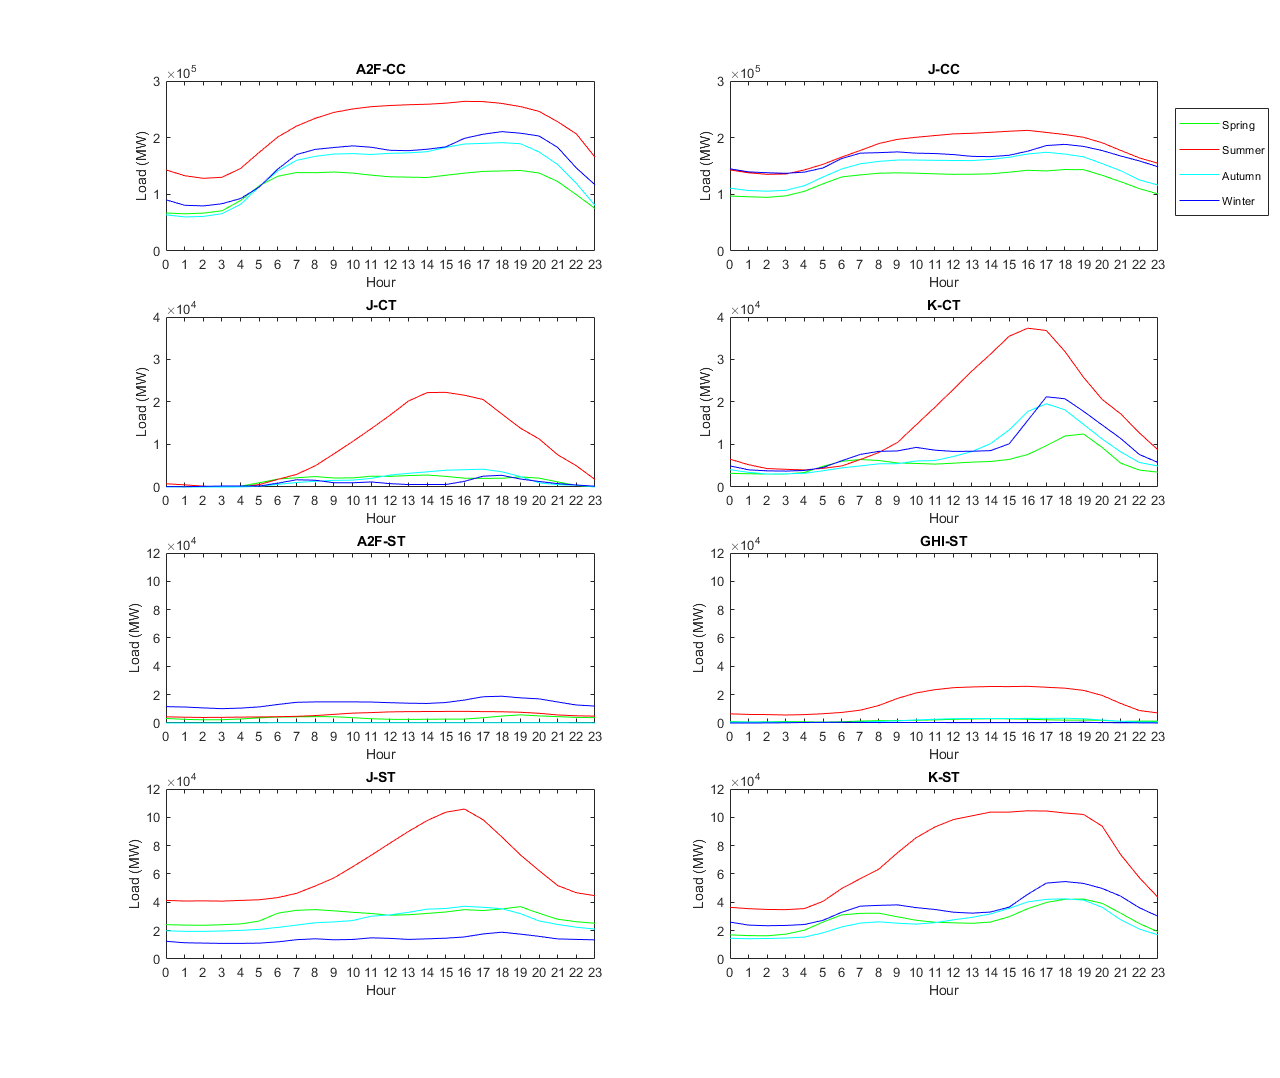

fPlot3 = figure(11);
clf('reset');
set(fPlot3, 'Units', 'pixels', 'Position', [0, 0, 1600, 1600]);
% A2F-CC
ax1 = subplot(4,2,1);
hold on;
plot(A2F_CC_SpringDaily.Hour, A2F_CC_SpringDaily.sum_GrossLoadMW, 'g-');
plot(A2F_CC_SummerDaily.Hour, A2F_CC_SummerDaily.sum_GrossLoadMW, 'r-');
plot(A2F_CC_AutumnDaily.Hour, A2F_CC_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(A2F_CC_WinterDaily.Hour, A2F_CC_WinterDaily.sum_GrossLoadMW, 'b-');
title("A2F-CC");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 3e5]);
xticks(0:23);
box on;
hold off;

% J-CC
ax2 = subplot(4,2,2);
hold on;
plot(J_CC_SpringDaily.Hour, J_CC_SpringDaily.sum_GrossLoadMW, 'g-');
plot(J_CC_SummerDaily.Hour, J_CC_SummerDaily.sum_GrossLoadMW, 'r-');
plot(J_CC_AutumnDaily.Hour, J_CC_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(J_CC_WinterDaily.Hour, J_CC_WinterDaily.sum_GrossLoadMW, 'b-');
title("J-CC");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 3e5]);
xticks(0:23);
box on;
hold off;

% J-CT
ax3 = subplot(4,2,3);
hold on;
plot(J_CT_SpringDaily.Hour, J_CT_SpringDaily.sum_GrossLoadMW, 'g-');
plot(J_CT_SummerDaily.Hour, J_CT_SummerDaily.sum_GrossLoadMW, 'r-');
plot(J_CT_AutumnDaily.Hour, J_CT_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(J_CT_WinterDaily.Hour, J_CT_WinterDaily.sum_GrossLoadMW, 'b-');
title("J-CT");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 4e4]);
xticks(0:23);
box on;
hold off;

% K-CT
ax4 = subplot(4,2,4);
hold on;
plot(K_CT_SpringDaily.Hour, K_CT_SpringDaily.sum_GrossLoadMW, 'g-');
plot(K_CT_SummerDaily.Hour, K_CT_SummerDaily.sum_GrossLoadMW, 'r-');
plot(K_CT_AutumnDaily.Hour, K_CT_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(K_CT_WinterDaily.Hour, K_CT_WinterDaily.sum_GrossLoadMW, 'b-');
title("K-CT");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 4e4]);
xticks(0:23);
box on;
hold off;

% A2F-ST
ax5 = subplot(4,2,5);
hold on;
plot(A2F_ST_SpringDaily.Hour, A2F_ST_SpringDaily.sum_GrossLoadMW, 'g-');
plot(A2F_ST_SummerDaily.Hour, A2F_ST_SummerDaily.sum_GrossLoadMW, 'r-');
plot(A2F_ST_AutumnDaily.Hour, A2F_ST_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(A2F_ST_WinterDaily.Hour, A2F_ST_WinterDaily.sum_GrossLoadMW, 'b-');
title("A2F-ST");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 1.2e5]);
xticks(0:23);
box on;
hold off;

% GHI-ST
ax6 = subplot(4,2,6);
hold on;
plot(GHI_ST_SpringDaily.Hour, GHI_ST_SpringDaily.sum_GrossLoadMW, 'g-');
plot(GHI_ST_SummerDaily.Hour, GHI_ST_SummerDaily.sum_GrossLoadMW, 'r-');
plot(GHI_ST_AutumnDaily.Hour, GHI_ST_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(GHI_ST_WinterDaily.Hour, GHI_ST_WinterDaily.sum_GrossLoadMW, 'b-');
title("GHI-ST");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 1.2e5]);
xticks(0:23);
box on;
hold off;

% J-ST
ax7 = subplot(4,2,7);
hold on;
plot(J_ST_SpringDaily.Hour, J_ST_SpringDaily.sum_GrossLoadMW, 'g-');
plot(J_ST_SummerDaily.Hour, J_ST_SummerDaily.sum_GrossLoadMW, 'r-');
plot(J_ST_AutumnDaily.Hour, J_ST_AutumnDaily.sum_GrossLoadMW, 'c-');
plot(J_ST_WinterDaily.Hour, J_ST_WinterDaily.sum_GrossLoadMW, 'b-');
title("J-ST");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 1.2e5]);
xticks(0:23);
box on;
hold off;

% K-ST
ax8 = subplot(4,2,8);
hold on;
p1 = plot(K_ST_SpringDaily.Hour, K_ST_SpringDaily.sum_GrossLoadMW, 'g-');
p2 = plot(K_ST_SummerDaily.Hour, K_ST_SummerDaily.sum_GrossLoadMW, 'r-');
p3 = plot(K_ST_AutumnDaily.Hour, K_ST_AutumnDaily.sum_GrossLoadMW, 'c-');
p4 = plot(K_ST_WinterDaily.Hour, K_ST_WinterDaily.sum_GrossLoadMW, 'b-');
title("K-ST");
xlabel("Hour");
ylabel("Load (MW)");
% legend(["Spring", "Summer", "Autumn", "Winter"]);
axis([0, 23, 0, 1.2e5]);
xticks(0:23);
box on;
hold off;

% Move subplot positions and add legend
fPlot3.Position(3) = fPlot3.Position(3) + 300;
% set(ax1, 'Position', [0.1, 0.76, 0.35, 0.15]);
% set(ax2, 'Position', [0.55, 0.76, 0.35, 0.15]);
% set(ax3, 'Position', [0.1, 0.52, 0.35, 0.15]);
% set(ax4, 'Position', [0.55, 0.52, 0.35, 0.15]);
% set(ax5, 'Position', [0.1, 0.3, 0.35, 0.15]);
% set(ax6, 'Position', [0.55, 0.3, 0.35, 0.15]);
% set(ax7, 'Position', [0.1, 0.1, 0.35, 0.15]);
% set(ax8, 'Position', [0.55, 0.1, 0.35, 0.15]);
hlegend = legend([p1, p2, p3, p4], ["Spring", "Summer", "Autumn", "Winter"]);
set(hlegend, 'Units', 'normalized', 'Position', [0.95, 0.8, 0.01, 0.1]);